# iTEBD: Hastings' method, orthonormalization

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

In this tutorial, we will practice two approaches that overcome the limitations of Vidal's original formulation of the iTEBD method.

- The first is Hastings' version of iTEBD, proposed in [[M. Hastings, J. Math. Phys. **50**, 095207 (2009)](https://aip.scitation.org/doi/abs/10.1063/1.3149556)], which avoids the division by small singular values. It will be implemented as Exercise (a).

- The second is the orthonormalization of an inifinite MPS in the $\Gamma$-$\Lambda$ notation, developed by [[R. Orus and G. Vidal, Phys. Rev. B **78**, 155117 (2008)](https://journals.aps.org/prb/abstract/10.1103/PhysRevB.78.155117)]. It will be implemented as Exercise (b) and used to obtain the scaling behavior of a spin-spin correlation function in Exercise (c).

## Exercise (a): Complete the function for Hastings' version of iTEBD

There is a function `iTEBD_GS_Hastings_Ex.m`, which is in the same sub-directory with this script. It is incomplete. Complete the parts enclosed by the comments `TODO (start)` and `TODO (end)`.

You can check your implementation of `iTEBD_GS_Hastings_Ex.m` by running the calculation of the spin-1 Heisenberg model on the infinite spin chain. Here we only modify the names of tensors, from `Gamma` to `As`.

clear

% iTEBD parameters
Nkeep = 30;
tau_ini = 1; % initial imaginary time step size
tau_fin = 1e-6; % final imaginary time step size
Nstep = 2e3; % number of imaginary time steps
taus = tau_ini*((tau_fin/tau_ini).^linspace(0,1,Nstep));
% discrete imaginary time steps; decays slowly but exponentially

% Local operators
[S,I] = getLocalSpace('Spin',1);

% Heisenberg interaction as two-site gate S*S'
H = contract(S,3,3,permute(conj(S),[2 1 3]),3,3);

% Initialize with random Lambda and Gamma
Lambda = cell(1,2);
Bs = cell(1,2);
for itn = (1:numel(Lambda))
    Lambda{itn} = rand(Nkeep,1);
    Bs{itn} = rand(Nkeep,Nkeep,size(I,2));
end

% iTEBD ground state search
[Lambda,Bs,Eiter] = iTEBD_GS_Hastings_Ex(Lambda,Bs,H,Nkeep,taus);

22-10-03 16:41:58 | iTEBD ground state search (Hastings' version): Nkeep = 30, # of imag. time steps = 2000
22-10-03 16:42:01 | #500/2000, E = -1.3992815
22-10-03 16:42:04 | #1000/2000, E = -1.4014172
22-10-03 16:42:06 | #1500/2000, E = -1.4014805
22-10-03 16:42:09 | #2000/2000, E = -1.4014825
Elapsed time: 10.95s, CPU time: 118.2s, Avg # of cores: 10.8
22-10-03 16:42:09 | Memory usage : 3.13GiB


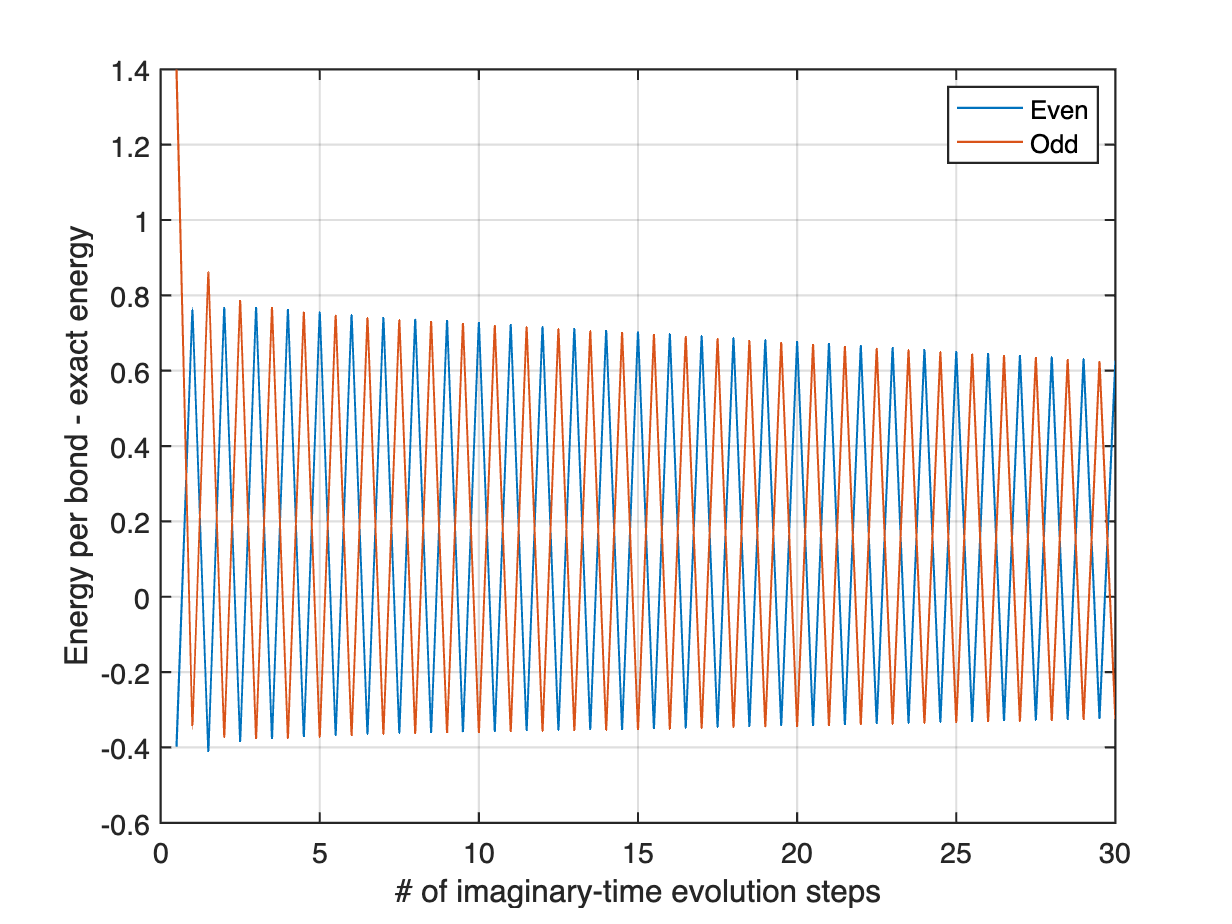

Eexact = -1.401484039;
% reshape Eiter for convenient plot
Eiter2 = reshape(permute(Eiter,[2 1 3]), ...
    [size(Eiter,2)*size(Eiter,1) size(Eiter,3)]);
figure;
plot((1:size(Eiter2,1)).'/2,Eiter2-Eexact,'LineWidth',1);
set(gca,'LineWidth',1,'FontSize',13,'YScale','linear');
xlim([0 30]);
xlabel('# of imaginary-time evolution steps');
ylabel('Energy per bond - exact energy');
legend({'Even','Odd'});
grid on;

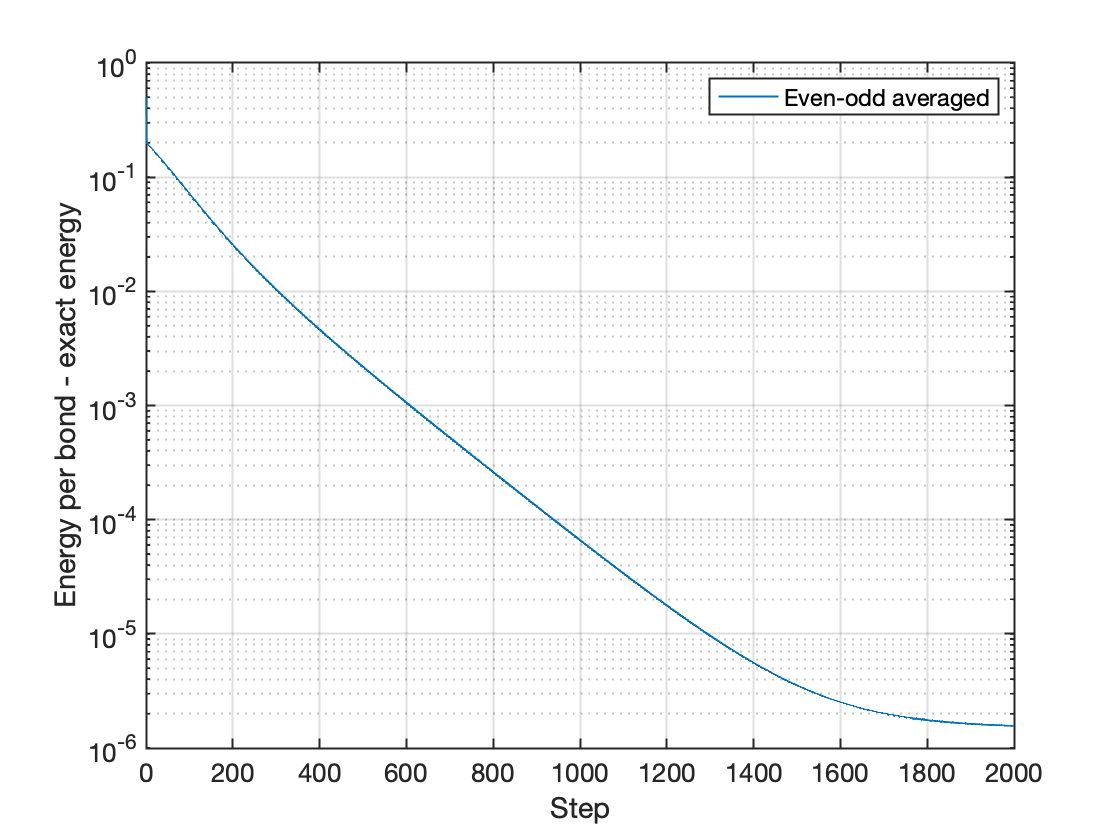

figure;
plot((1:size(Eiter2,1)).'/2,mean(Eiter2,2)-Eexact,'LineWidth',1);
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
xlabel('Step');
ylabel('Energy per bond - exact energy');
legend({'Even-odd averaged'});
grid on;

## Exercise (b): Complete the function for the orthonormalization

There is a function `ortho_Orus_Ex.m`, which is in the same sub-directory with this script. It is incomplete. Complete the parts enclosed by the comments `TODO (start)` and `TODO (end)`.

## Exercise (c): Correlation length of the spin-1 Heisenberg model

In this Exercise, we will investigate a spin-spin correlation function $\langle \hat{S}_{\ell,z} \hat{S}_{\ell+n,z} \rangle$ for the spin-1 Heisenberg model on the infinite spin chain. The scaling behavior of the correlation function for large distance $n$ can be identified by analyzing transfer operators, as we discussed in the lecture on translationally invariant MPS. The transfer operators, however, need to be constructed from the orthonormalized tensors, since the scaling analysis rely on the left- or right-normalization of the tensors. Therefore, here we obtain the orthonormalized tensors by applying `ortho_Orus_Ex.m` to the result from Vidal's iTEBD. (You can also use Hastings' version as well, but the current implementation of `ortho_Orus_Ex.m` is based on the $\Gamma$-$\Lambda$ notation, not on the left- or right-normalized tensors used by Hastings' version.)

(i) Show that, for even and large $n \gg 1$, the correlation decays exponentially, $\langle \hat{S}_{\ell,z} \hat{S}_{\ell+n,z} \rangle \sim \exp ( - n /\xi)$, by constructing and analyzing transfer operators for the two-site unit cell.

(ii) Analyze how the correlation length $\xi$ changes with different `Nkeep`'s. (*Hint*: Indeed, $\xi$ depends on the maximum bond dimension $N_\mathrm{keep}$ (`Nkeep`). In the limit of $N_\mathrm{keep} \to \infty$, it will converge to $\xi \simeq 6$, as found in [[S. R. White and D. A. Huse, Phys. Rev. B **48**, 3844 (1993)](https://journals.aps.org/prb/abstract/10.1103/PhysRevB.48.3844)]).